Copyright 2022 - 2022 The MathWorks, Inc.

## This Live Editor can setup parameter for Dual Active bridge model

%Parameters
Vin = 380;
Vout = 48;
N = 5;
Fsw = 100000

Fsw = 100000

Tsw = 1 / Fsw;
%Ltyp
LTyp =0.000045

LTyp = 4.5000e-05

Tlpf = 1 / (2 * pi * Fsw/10);

%Create dataset for plot,グラフ描画のために位相シフト率のデータセット用意
t = 0:0.01:1;
ThetaRatio_t = 0.25 * t; 

%Define width of change of Indactance / インダクタンスばらつき幅定義
L = [LTyp * 0.8; LTyp; LTyp*1.2];

% Dual Active Bridge phase shift amount and current/voltage relational expression 
% Dual Active Bridge位相シフト量と電流、電圧の関係式を計算



$$I_{\textrm{in}\;} \left(\phi \right)=\frac{V_{\textrm{in}} T_{\textrm{Sw}} \phi -\left|1-2\phi \right|}{L}$$


$\varphi_d$:Phase shift amount[%]


Iin = (Vin * Tsw .*ThetaRatio_t - Vin * 2 *Tsw .*ThetaRatio_t.*ThetaRatio_t) ./ L;
Pin = Iin * Vin;
lh= int16(length(ThetaRatio_t)/2)

lh = int16
51

p = polyfit(ThetaRatio_t(1:lh),Iin(2,1:lh),1);
ApproximateIin = p(1)*ThetaRatio_t+p(2);


## Plot

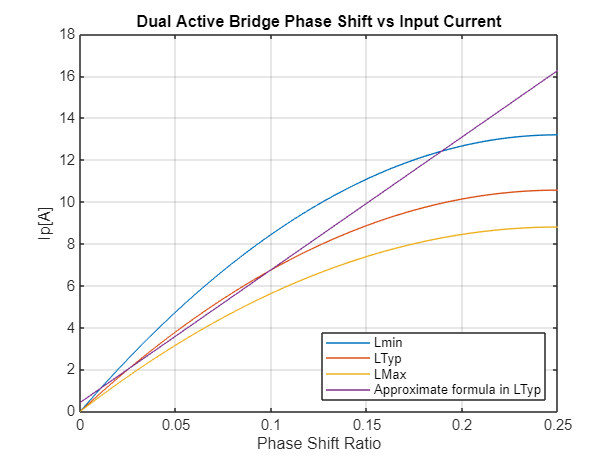

plot(ThetaRatio_t,Iin);
hold on
plot(ThetaRatio_t,ApproximateIin)
xlabel('Phase Shift Ratio');
ylabel('Ip[A]');
grid on;
legend({'Lmin','LTyp','LMax','Approximate formula in LTyp'},'Location','southeast')
title("Dual Active Bridge Phase Shift vs Input Current")

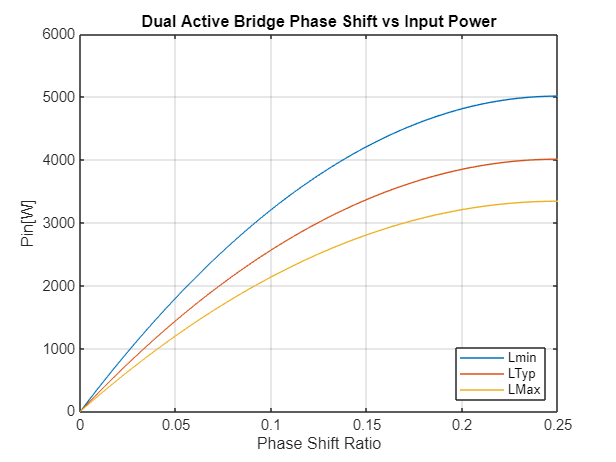

figure;

plot(ThetaRatio_t,Pin);
xlabel('Phase Shift Ratio');
ylabel('Pin[W]');
grid on;
legend({'Lmin','LTyp','LMax'},'Location','southeast')
title("Dual Active Bridge Phase Shift vs Input Power")